## [TB]이 파일로 한 속도에서 한다음에 파일을 만들어서 속도별로 하는걸로 변경

## MCAD GetData


rpm = 8000

% dev_e10_ACLoss - Branch - 삭제할것
% MachineData From MCAD
addpwd
mcad=callMCAD
refPath='Z:\Simulation\JEETACLossValid_e10_v24\refModel\e10_UserRemesh.mot';
if ~exist(refPath,"file")
    refPath='D:\KangDH\Thesis\e10\refModel\e10_UserRemesh.mot';
end
[refDIR,FileName,~]=fileparts(refPath);
[~,curMotFilePath]=mcad.GetVariable('CurrentMotFilePath_MotorLAB')
if ~strcmp(curMotFilePath,refPath)
mcad.LoadFromFile(refPath)
end 
% get MachineData
MachineData=defMCADMachineData4Scaling(mcad)
[~,RMSCurrent]=mcad.GetVariable('RMSCurrent');
[~,MCADPhaseAdvance]=mcad.GetVariable('PhaseAdvance');
FreqE=rpm2freqE(rpm,MachineData.Pole_Number/2)

% cad Periodicity

### Fig 11. B wave form

[..\tools\loss\ACLOSS\MCAD\devCalcMCADHybridACLoss.mlx](matlab:open('..\tools\loss\ACLOSS\MCAD\devCalcMCADHybridACLoss.mlx'))

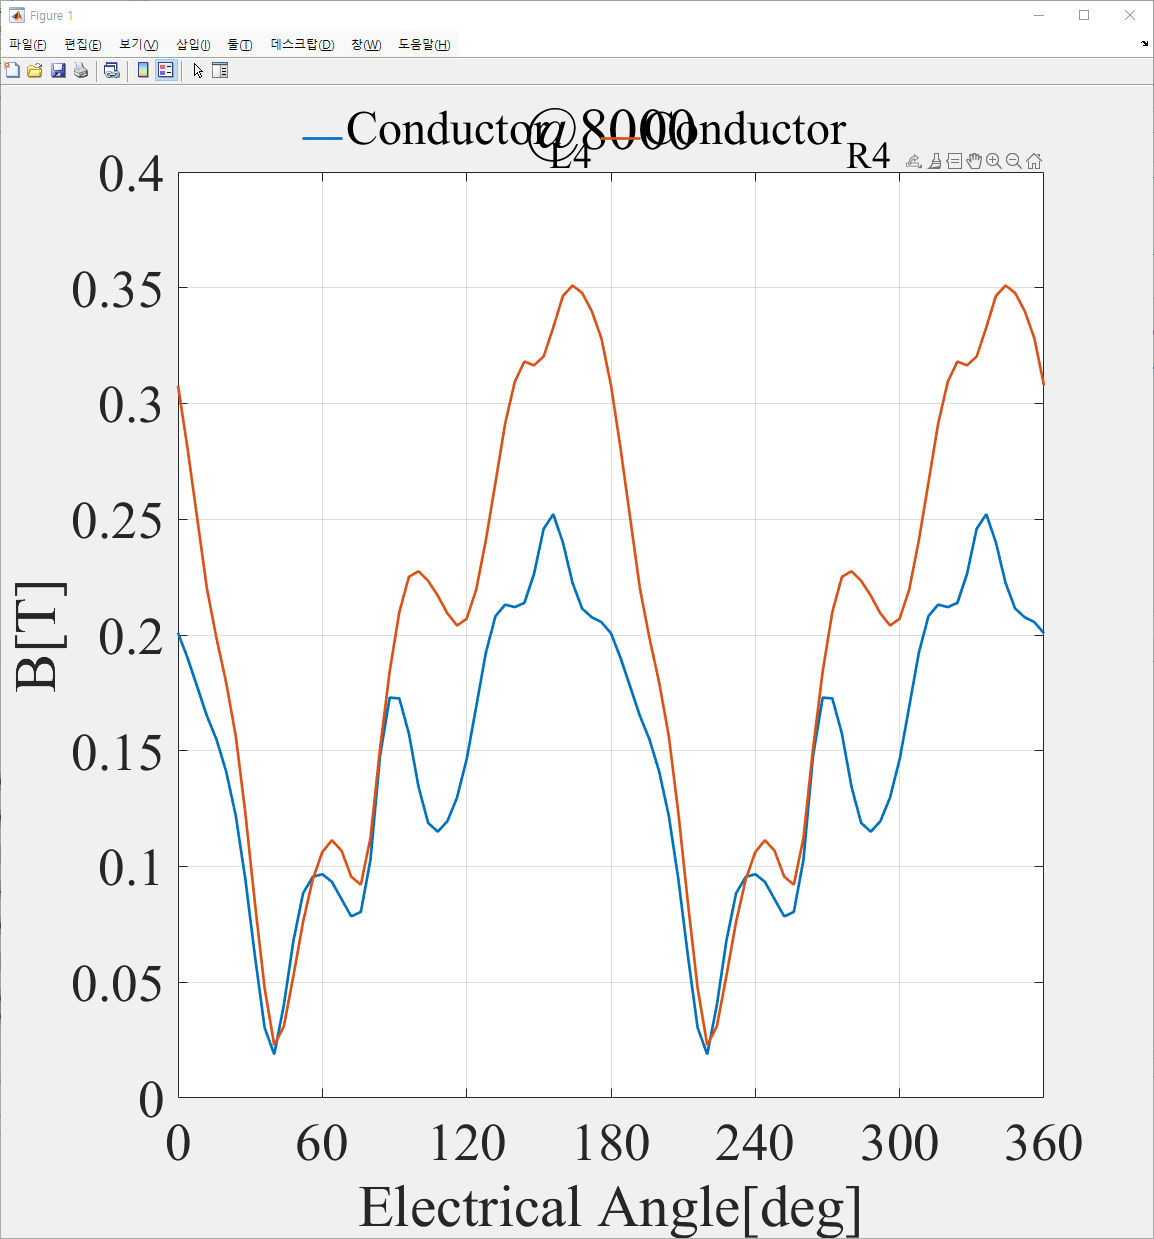

%% MotFileName
[refDIR,FileName,~]=fileparts(refPath)
% Conductor
PartName ='Stator'
settingDXFTable    =defMCADDXFExportSettingVariable(PartName);
testStatorDXFPath  =fullfile(refDIR,[FileName,PartName,'_Origin.dxf'])
settingDXFTable.CurrentValue(contains(settingDXFTable.AutomationName,'FileName'))={testStatorDXFPath};
setMcadTableVariable(settingDXFTable,mcad)
mcad.GeometryExport()
PartName ='Rotor'
settingDXFTable    =defMCADDXFExportSettingVariable(PartName);
testRotorDXFPath   =fullfile(refDIR,[FileName,PartName,'_Origin.dxf'])
settingDXFTable.CurrentValue(contains(settingDXFTable.AutomationName,'FileName'))={testRotorDXFPath};
setMcadTableVariable(settingDXFTable,mcad)
mcad.GeometryExport()
%% WriteDXF
entitiesStatorStruct        =readDXF(testStatorDXFPath)
entitiesStatorStruct        =arrayfun(@(x) setfield(x, 'layer', 'stator'), entitiesStatorStruct);
StatrDxf                    =filterEntitiesByAngle(entitiesStatorStruct, 45);
StatrDxf.entities           =entitiesStatorStruct
StatrDxf.divisions=200
plotEntitiesStruct(StatrDxf)
NewtestStatorDXFPath        =strrep(testStatorDXFPath,'Origin','');
[~,NewtestStatorDXFPath,~]  =fileparts(NewtestStatorDXFPath);
NewtestStatorDXFPath        =fullfile(refDIR,[NewtestStatorDXFPath,'_Periodic','.dxf'])
writeDXF(NewtestStatorDXFPath, StatrDxf)

### rev1에서 회전자 dxf 수정함

dxfFiles = findDXFFiles(refDIR)';

MPToolCSVFilePath = 'Z:/Simulation/JEETACLossValid_e10_v24/refModel/ExportMPtools/baseName.csv'

entitiesRotorStruct = readDXF(dxfFiles{1})
entitiesRotorStruct = arrayfun(@(x) setfield(x, 'layer', 'rotor'), entitiesRotorStruct);
RotorDxf = filterEntitiesByAngle(entitiesRotorStruct, 22.5);
plotEntitiesStruct(RotorDxf)
NewtestRotorDXFPath         =strrep(testRotorDXFPath,'Origin','');
[~,NewtestRotorDXFPath,~]   =fileparts(NewtestRotorDXFPath);
NewtestRotorDXFPath         =fullfile(refDIR,[NewtestRotorDXFPath,'_Periodic','.dxf']);
% delete(dxfFiles{:})
writeDXF(NewtestRotorDXFPath, RotorDxf);
dxfFiles = findDXFFiles(refDIR)';

#### dxfList2Import

dxfList2Import=defDXFList2Import(dxfFiles, 1,2)
dxfList2Import.dxfPath{1}=NewtestStatorDXFPath  ;
dxfList2Import.dxfPath{2}=NewtestRotorDXFPath  ;


## JMAG

### e10MS

e10MS

%Z:\01_Codes_Projects\git_fork_emach\tools\loss\VeriCalcHybridACLossModelwithSlotB.mlx

#### JEET Figure Number

#### MQS 같은데 mesh 플로팅

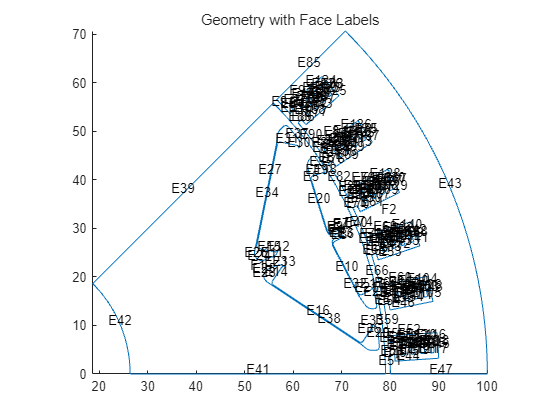

MPToolCSVFilePath='Z:/Simulation/JEETACLossValid_e10_v24/refModel/ExportMPtools/baseName.csv'
[model,pdeTriElements,pdeNodes,pdeQuadElements]  = nastran2PDEMesh(MPToolCSVFilePath);

% 일단 dxf와 nastran으로 매칭시키기
% airgap영역도 정보 가져와야됨

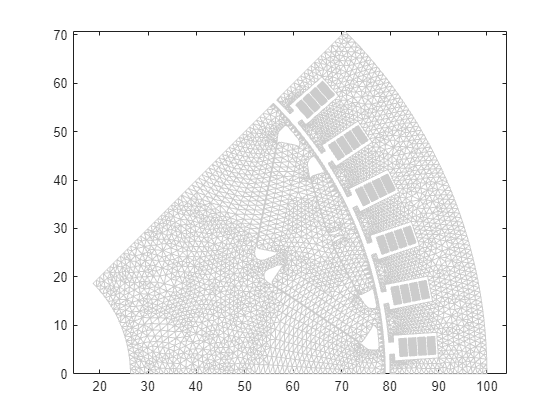

% 영역만들기
% drawFluxDensity 
%

% load mcad 어디까지 되는지 

figure(2)
% 색상을 설정합니다.
% 각 영역을 시각화하여 구분합니다.
pdegplot(model, 'FaceLabels', 'on', 'EdgeLabels', 'on');

FieldData_perStep = 다음 필드를 포함한 struct :
      step1: [6652×7 table]
      step2: [6652×7 table]
      step3: [6652×7 table]
      step4: [6652×7 table]
      step5: [6652×7 table]
      step6: [6652×7 table]
      step7: [6652×7 table]
      step8: [6652×7 table]
      step9: [6652×7 table]
     step10: [6652×7 table]
     step11: [6652×7 table]
     step12: [6652×7 table]
     step13: [6652×7 table]
     step14: [6652×7 table]
     step15: [6652×7 table]
     step16: [6652×7 table]
     step17: [6652×7 table]
     step18: [6652×7 table]
     step19: [6652×7 table]
     step20: [6652×7 table]
     step21: [6652×7 table]
     step22: [6652×7 table]
     step23: [6652×7 table]
     step24: [6652×7 table]
     step25: [6652×7 table]
     step26: [6652×7 table]
     step27: [6652×7 table]
     step28: [6652×7 table]
     step29: [6652×7 table]
     step30: [6652×7 table]
     step31: [6652×7 table]
     step32: [6652×7 table]
     step33: [6652×7 table]
     step34: [6652×7 table]
     ste

title('Geometry with Face Labels');
numFaces = model.Geometry.NumFaces;

colors = lines(numFaces); % 각 Face에 대해 다른 색상을 생성합니다.

figure;
pdemesh(model)

x = pdeNodes(1,:);
y = pdeNodes(2,:);
hold on
quadmesh(pdeQuadElements, x, y);
centerAllFigures
% 색상을 설정합니다.
line_handles = findobj(gca, 'Type','line');
set(line_handles, 'Color', [0.8,0.8,0.8]); % 예: 검은색



Fig 9 MVP Contour

keyword='11005'; % MVP
% keyword='16001'; % B
FieldData_perStep = extractJMAGFieldVectorFromMPtoolCSV(MPToolCSVFilePath, keyword)
% csvFile=MPToolCSVFilePath
FieldData_perStep.step1
% 노드 좌표 설정

[TC]Fig 10 Slot Flux Density Contour -> Fig 8 flux density contour

addpath(genpath('Z:\01_Codes_Projects\git_SMEKlib'))
MeshPDEtoolForm=model.Mesh;
[PetFor.p,PetFor.e,PetFor.t]=MeshPDEtoolForm.meshToPet();
PetFor.t(4,:)=[]
msh=PetFor

stepNameList=fieldnames(FieldData_perStep)

for i=60:1:60
% A=Az{:,i}
A=FieldData_perStep.(stepNameList{i}).vecz;
% figure(i)
[p_plot, plotArgs] = aux_Plotting_parseInput(msh);
t = msh.t;
I = 1;

drawFluxDensity(msh, A); 
end

#### Fig 11. Slot Flux Density waveform- Jmag - manual import [Coil]

% 가져오기 옵션을 설정하고 데이터 가져오기
opts = delimitedTextImportOptions("NumVariables", 125);

유효하지 않은 표현식입니다. 누락되거나 불필요한 문자가 있는지 확인하십시오.


% 범위 및 구분 기호 지정
opts.DataLines = [3, Inf];
opts.Delimiter = ",";

% 열 이름과 유형 지정
opts.VariableNames = ["ElementID", "Step1_R", "Step2_R", "Step3_R", "Step4_R", "Step5_R", "Step6_R", "Step7_R", "Step8_R", "Step9_R", "Step10_R", "Step11_R", "Step12_R", "Step13_R", "Step14_R", "Step15_R", "Step16_R", "Step17_R", "Step18_R", "Step19_R", "Step20_R", "Step21_R", "Step22_R", "Step23_R", "Step24_R", "Step25_R", "Step26_R", "Step27_R", "Step28_R", "Step29_R", "Step30_R", "Step31_R", "Step32_R", "Step33_R", "Step34_R", "Step35_R", "Step36_R", "Step37_R", "Step38_R", "Step39_R", "Step40_R", "Step41_R", "Step42_R", "Step43_R", "Step44_R", "Step45_R", "Step46_R", "Step47_R", "Step48_R", "Step49_R", "Step50_R", "Step51_R", "Step52_R", "Step53_R", "Step54_R", "Step55_R", "Step56_R", "Step57_R", "Step58_R", "Step59_R", "Step60_R", "Step61_R", "Step62_R", "Step63_R", "Step64_R", "Step65_R", "Step66_R", "Step67_R", "Step68_R", "Step69_R", "Step70_R", "Step71_R", "Step72_R", "Step73_R", "Step74_R", "Step75_R", "Step76_R", "Step77_R", "Step78_R", "Step79_R", "Step80_R", "Step81_R", "Step82_R", "Step83_R", "Step84_R", "Step85_R", "Step86_R", "Step87_R", "Step88_R", "Step89_R", "Step90_R", "Step91_R", "Step92_R", "Step93_R", "Step94_R", "Step95_R", "Step96_R", "Step97_R", "Step98_R", "Step99_R", "Step100_R", "Step101_R", "Step102_R", "Step103_R", "Step104_R", "Step105_R", "Step106_R", "Step107_R", "Step108_R", "Step109_R", "Step110_R", "Step111_R", "Step112_R", "Step113_R", "Step114_R", "Step115_R", "Step116_R", "Step117_R", "Step118_R", "Step119_R", "Step120_R", "Step121_R", "PositionX", "PositionY", "PositionZ"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% 파일 수준 속성 지정
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% 데이터 가져오기
BrLoad = readtable("Z:\Simulation\JEETACLossValid_e10_v24\refModel\e10_v24.jfiles\BrLoad.csv", opts);

% 임시 변수 지우기
clear opts

% 결과 표시
BrLoad

% 가져오기 옵션을 설정하고 데이터 가져오기
opts2 = delimitedTextImportOptions("NumVariables", 125);

% 범위 및 구분 기호 지정
opts2.DataLines = [3, Inf];
opts2.Delimiter = ",";

% 열 이름과 유형 지정
opts2.VariableNames = ["ElementID", "Step1__", "Step2__", "Step3__", "Step4__", "Step5__", "Step6__", "Step7__", "Step8__", "Step9__", "Step10__", "Step11__", "Step12__", "Step13__", "Step14__", "Step15__", "Step16__", "Step17__", "Step18__", "Step19__", "Step20__", "Step21__", "Step22__", "Step23__", "Step24__", "Step25__", "Step26__", "Step27__", "Step28__", "Step29__", "Step30__", "Step31__", "Step32__", "Step33__", "Step34__", "Step35__", "Step36__", "Step37__", "Step38__", "Step39__", "Step40__", "Step41__", "Step42__", "Step43__", "Step44__", "Step45__", "Step46__", "Step47__", "Step48__", "Step49__", "Step50__", "Step51__", "Step52__", "Step53__", "Step54__", "Step55__", "Step56__", "Step57__", "Step58__", "Step59__", "Step60__", "Step61__", "Step62__", "Step63__", "Step64__", "Step65__", "Step66__", "Step67__", "Step68__", "Step69__", "Step70__", "Step71__", "Step72__", "Step73__", "Step74__", "Step75__", "Step76__", "Step77__", "Step78__", "Step79__", "Step80__", "Step81__", "Step82__", "Step83__", "Step84__", "Step85__", "Step86__", "Step87__", "Step88__", "Step89__", "Step90__", "Step91__", "Step92__", "Step93__", "Step94__", "Step95__", "Step96__", "Step97__", "Step98__", "Step99__", "Step100__", "Step101__", "Step102__", "Step103__", "Step104__", "Step105__", "Step106__", "Step107__", "Step108__", "Step109__", "Step110__", "Step111__", "Step112__", "Step113__", "Step114__", "Step115__", "Step116__", "Step117__", "Step118__", "Step119__", "Step120__", "Step121__", "PositionX", "PositionY", "PositionZ"];
opts2.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% 파일 수준 속성 지정
opts2.ExtraColumnsRule = "ignore";
opts2.EmptyLineRule = "read";

% 데이터 가져오기
BtLoad = readtable("Z:\Simulation\JEETACLossValid_e10_v24\refModel\e10_v24.jfiles\BtLoad.csv", opts2);

% 임시 변수 지우기
clear opts2

% 결과 표시
BtLoad



% 변수(열) 이름에서 'position' 문자열이 포함된 열 찾기
idx = contains(BrLoad.Properties.VariableNames, 'position','IgnoreCase',true);
BrLoad = setVarAsRowNames(BrLoad, 'ElementID');
BrLoad = removevars(BrLoad,'ElementID')


idx = contains(BtLoad.Properties.VariableNames, 'position','IgnoreCase',true);
BtLoad = setVarAsRowNames(BtLoad, 'ElementID');
BtLoad = removevars(BtLoad,'ElementID')

%% array
B1=BrLoad(:,~idx)
B1Matrix=B1.Variables
B2=BtLoad(:,~idx)
B2Matrix=B2.Variables

Babs=sqrt(B1.Variables.^2+B2.Variables.^2)

%% get Position Table
positionTable = BtLoad(:, idx);

PartStruct=getJMAGDesignerPartStruct(app);
idx=findMatchingIndexInStruct(PartStruct,'Name','Conductor')
WireStruct=PartStruct(idx)

%% Get Wire Element and Node ID
for Index=1:length(WireStruct)
    WireIndex=WireStruct(Index).partIndex;
    [WireStruct(Index).ElementId, WireStruct(Index).NodeID]=devgetMeshData(app,WireIndex)
end

[ElementID, NodeID]=devgetMeshData(app,PartIndex)

% elementID 
% R4ID=
L4ID=3942
L3ID=3939
R4ID=3924
R3ID=3921
R4r=B1(num2str(R4ID),:).Variables
R4t=B2(num2str(R4ID),:).Variables
L4r=B1(num2str(L4ID),:).Variables
L4t=B2(num2str(L4ID),:).Variables
BL4abs=sqrt(L4r.^2+L4t.^2)

%% 
R4=[]
L4=[]
L3=[]
R3=[]
figure(1)
L4Data.DisplayName='Left'
L4Data.PlotType=''
L4Data.Unit='[T]'
hold on
plotXYarray([0:3:360],L4r,L4Data)
plotXYarray([0:3:360],L4t,L4Data)
plotXYarray([0:3:360],BL4abs,L4Data)
% Compare MCAd
conductorIndex=8
[shifted_signalJMAG, phase_shift] = align_signals(BL4abs, [0:3:360], opData.Wave.BCoductor{conductorIndex}.dataTable.GraphValue, opData.Wave.BCoductor{conductorIndex}.dataTable(:,2).Variables,-2, 'linear')
plotXYarray([0:3:360],shifted_signalJMAG,L4Data)


legendName=legend
legendName.String={'Left','L4r','L4t','L4abs'}
hold on
R4Data.DisplayName='Right'
R4Data.PlotType=''
plotXYarray([0:3:360],R4,R4Data)
adjustFiguresize(1,0.5)
adjustAxisLimit(1,1)


figure(2)
L3Data.DisplayName='Left'
L3Data.PlotType=''
plotXYarray([0:3:360],L3,L3Data)
hold on
R3Data.DisplayName='Right'
R3Data.PlotType=''
plotXYarray([0:3:360],R3,R3Data)
adjustFiguresize(1,0.5)
adjustAxisLimit(1,2)


#### Fig 12. Hybrid AC Loss Waveform

% 선행 정보 추출
McadIndex=1
conductorType='rectangular'
[~, SimulationSmall.ShaftSpeed]    = mcad(McadIndex).GetVariable('ShaftSpeed');
[~, SimulationSmall.pole]          = mcad(McadIndex).GetVariable('Pole_Number');
[~, Copper_Width]                  = mcad(McadIndex).GetVariable('Copper_Width');
[~, Copper_Height]                 = mcad(McadIndex).GetVariable('Copper_Height');
[~, Stator_Lam_Length]             = mcad(McadIndex).GetVariable('Stator_Lam_Length');
% freqE=rpm2freqE(SimulationSmall.ShaftSpeed,SimulationSmall.pole/2)
dimensions=[Copper_Width,Copper_Height,Stator_Lam_Length]

#### calc와 mcad비교

devCalcMCADHybridACLoss 에서 

- 단일 B값으로 OuputData와 비교           - 현재 일단 안맞음

- Graph값으로 비교 - outputData와 비교 : 

-  MCAD 그래프 가져오기

-  loadMCADSimulData로 그래프(B,AC) 불러오기, 이거기준으로 비교 - 1000*48 비율했는데 이것도 잘안맞음

- jmag과도 B값 position때문에 2D로 하더라도 다름

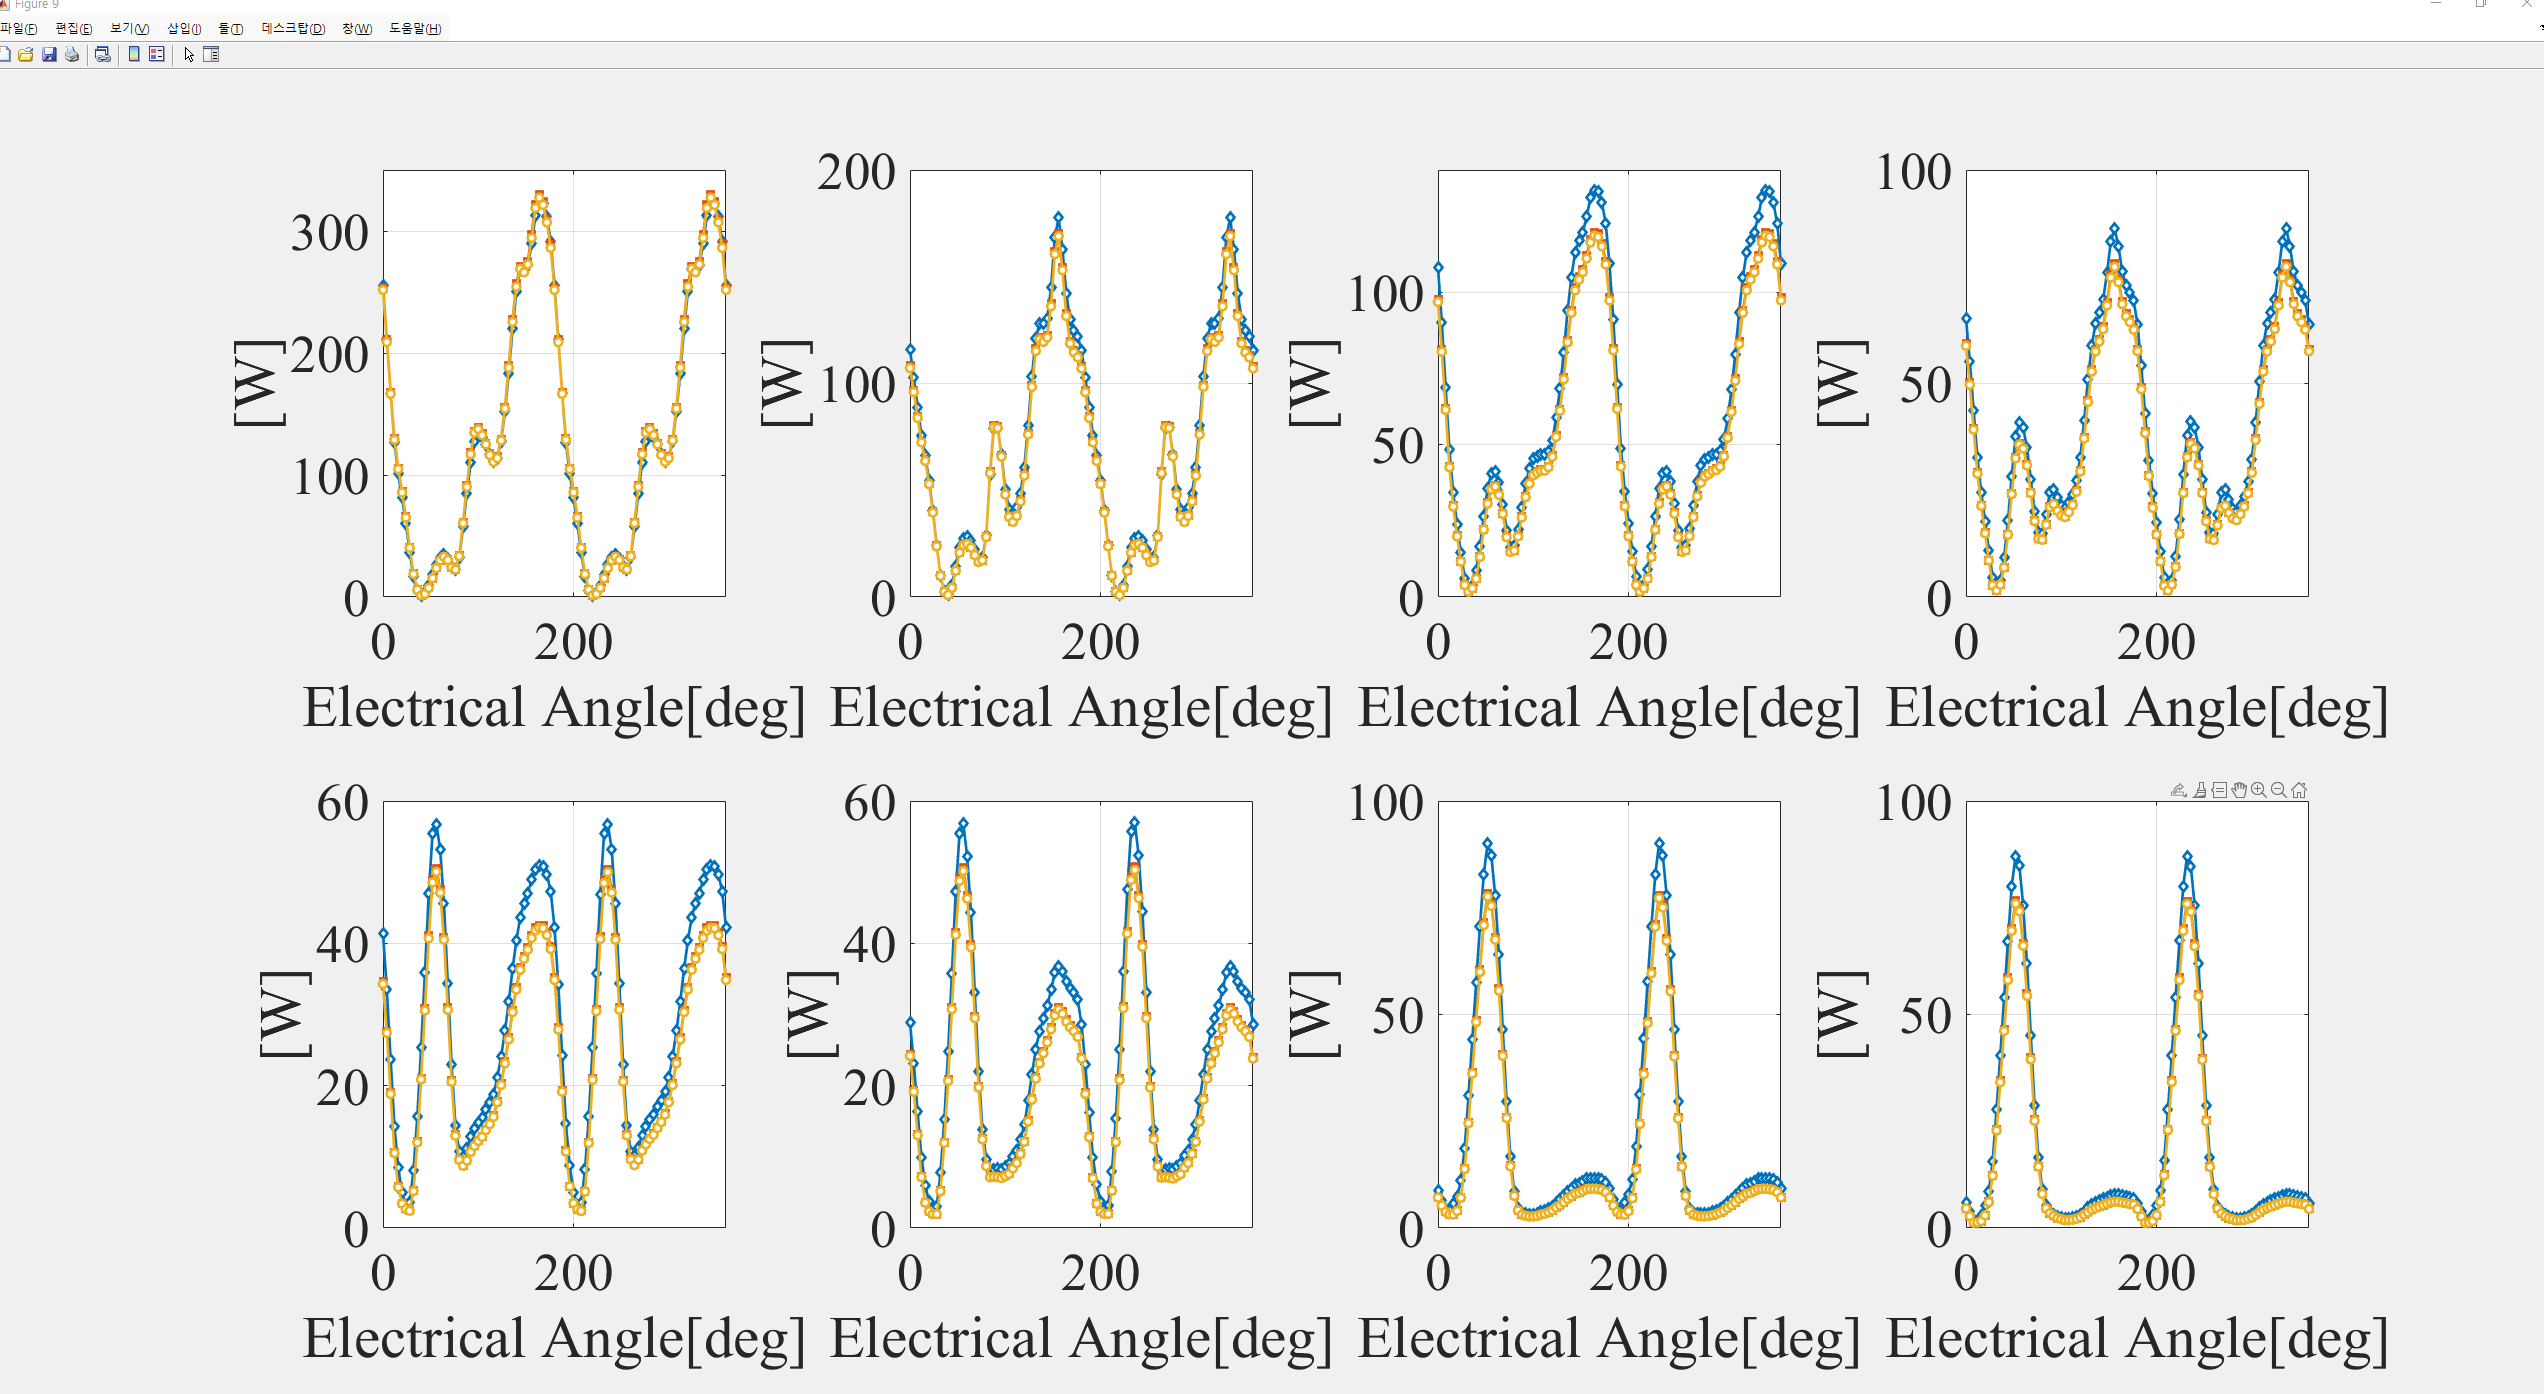

% MCAD
hybridACLossModelStr=devCalcMCADHybridACLoss(mcad)

CuboidModel          =hybridACLossModelStr.CuboidModel;
Cuboid_Width         =unique(CuboidModel.Winding_Cuboid_Width);
Cuboid_Height        =unique(CuboidModel.Winding_Cuboid_Height);
% B
for ConductorIndex=8:8
% ConductorIndex=8
ACLossCoductorWave=hybridACLossModelStr.OpDataGraph.Wave.ACLossCoductor
PMCADACLoss=ACLossCoductorWave{ConductorIndex}.dataTable.GraphValue
BWave=hybridACLossModelStr.OpDataGraph.Wave.BCoductor
BfieldMCAD=BWave{ConductorIndex}
BField=BfieldMCAD
% dimensions=[Cuboid_Width,Cuboid_Height,lactive]
[P_rect,P_1DInstant,P_1DrectG1,P1DrectG2,P_rect_nonGamma,P_rectMCAD1D,P_rec2DG1,P_rec2DG2]= calcHybridACLossWave(conductorType, dimensions, FreqE,BfieldMCAD)
figure(ConductorIndex)
plotXYarray([0:360/90:360],PMCADACLoss',P_rect1DData);
meanGraphAC=mean(PMCADACLoss')
hybridACLossModelStr.OutputDatabyMcad.PacLeft
hold on
plotXYarray([0:360/90:360],48*P_rectMCAD1D',P_rect1DData);
a=1000*48*P_rectMCAD1D
plotXYarray([0:360/90:360],48*P1DrectG2',P_rect1DData);
% shifted_signalMCAD = circshift(P_rec2DJMAG, -20);
% plotXYarray([0:3:360],shifted_signalMCAD,P_rect1DData);
% plotXYarray([0:360/90:360],48*P_1DrectG1',P_rect1DData);
% hold on
% plotXYarray([0:360/90:360],48*P_rect',P_rect1DData);
% plotXYarray([0:360/90:360],48*P_1DInstant',P_rect1DData);
end
% combineFiguresIntoSubplots

% jmag
Bfield4LayerLeft.Br         =L4r 
Bfield4LayerLeft.Bthetam    =L4t        
[P_rectJMAG,P_1DInstantJMAG,P_1DrectG1JMAG,P1DrectG2JMAG,P_rect_nonGammaJMAG,P_rectMCAD1DJMAG,P_rec2DJMAGG1,P_rec2DJMAGG2]= calcHybridACLossWave(conductorType, dimensions, FreqE,Bfield4LayerLeft)
conductorIndex=8
% [shifted_signalJMAG, phase_shift] = align_signals(P_rec2DJMAG, [0:3:360], PMCADACLoss', [0:360/90:360],-2, 'linear')
figure(conductorIndex)
hold on
shifted_signal2DJMAGG2   =48*circshift(P_rec2DJMAGG2, -21);
shifted_signal1DMCADJMAG =48*circshift(P_rectMCAD1DJMAG, -21);
shifted_signal2DJMAGG1   =48*circshift(P_rec2DJMAGG1, -21);

P_rect1DData.Unit='W'
P_rect1DData.PlotType=''
P_rect1DData.DisplayName='MS'
% plotXYarray([0:3:360],shifted_signal2DJMAGG2,P_rect1DData);
% plotXYarray([0:3:360],shifted_signal2DJMAGG1,P_rect1DData);
plotXYarray([0:3:360],shifted_signal1DMCADJMAG,P_rect1DData);
hold on
plotXYarray([0:3:360],shifted_signal2DJMAGG1,P_rect1DData);

plotXYarray([0:3:360],shifted_signal2DJMAGG2,P_rect1DData);

% legendName=legend
% legendName.String={'1D','2D','MCAD'}

#### Locus 그려서 1D로 할지 2D로 할지 결정

plotVectorFieldLocus(positionTable, BxMatrix, ByMatrix)

### e10MQS

e10MQS



#### Circuit Modeling

% [TC]winding From MCAD
windingPatternTxtPath ='Z:\Simulation\JEETACLossValid_e10_v24\refModel\e10_8p48s2Para4turn.txt'
[McadWindingPatternTable, MachineInfo]=readMCADWindingPatterTXT(windingPatternTxtPath)
outputPath=convertMCAD2JmagWireTable(McadWindingPatternTable)
% generate Winding Table

%

% 3Phase Circuit Component
InputCurrentData.pole=8
InputCurrentData.slot=48
InputCurrentData.ParallelNumber=2
PhaseStruct = mkConductorCircuit(8,48,2, CoilList, app, 70)
PhaseStruct(1).ParaStruct.ComponentTable
ConductorPartTable
% Input Circuit Component
InputPosition=[-17,56]
[compObj,InstanceObj]=mkJmag3PhaseSinInput(app,InputPosition)
TerminalPositionList{1}=[InputPosition(1)+2,InputPosition(2)+2];
TerminalPositionList{2}=[InputPosition(1)+2,InputPosition(2)];
TerminalPositionList{3}=[InputPosition(1)+2,InputPosition(2)-2];

% Connect
for PhaseIndex=1:3
      %% Connect each phase to Input
        StartPosition=PhaseStruct(PhaseIndex).StartPosition
        TerminalPosition=TerminalPositionList{PhaseIndex};
        curCircuitObj.CreateWire(StartPosition(3)-2, StartPosition(4), TerminalPosition(1),StartPosition(4));
        curCircuitObj.CreateWire(TerminalPosition(1),StartPosition(4), TerminalPosition(1),TerminalPosition(2));
end


### e10MQS_wireTemp

% \mlxperPJT\JEET\e10MQS_WireTemplate.m

## Plot

% Joule Loss [W]

%% get ResultTable Obj
app=callJmag
Model=app.GetCurrentModel
StudyIndex=5
curStudyObj=Model.GetStudy(StudyIndex-1)
LossStudyResultTableObj=curStudyObj.GetResultTable
% get DataStruct
ResultDataStruct  = getJMagResultDatas(LossStudyResultTableObj,'voltage')
currentDataStruct = getJMagResultDatas(LossStudyResultTableObj,'current')
jouleDataStruct   = getJMagResultDatas(LossStudyResultTableObj,'Joule')

% DC Loss  [W]
% total Current
uList=contains(currentDataStruct(1).dataTable.Properties.VariableNames,'u','IgnoreCase',true)
uITable=currentDataStruct(1).dataTable(:,uList);
uIVar=currentDataStruct(1).dataTable(:,uList).Variables;

% single Conductor - U1C1
u1C1List=contains(currentDataStruct(1).dataTable.Properties.VariableNames,'U1C1','IgnoreCase',true)
u1C1Table=currentDataStruct(1).dataTable(:,u1C1List);
u1C1Var=currentDataStruct(1).dataTable(:,u1C1List).Variables;
SingleRphaseMCAD = resitivity2Resistance(mm2m(150*2), SingleCoilAreaInSqm, resitivitityMCAD)
DCLossWaveu1C1Var=4*SingleRphaseMCAD*u1C1Var(:,1).^2
plot(u1C1Var(361:1:481,:))
hold on
plot(DCLossWaveu1C1Var(361:1:481,:))

% single Conductor - U2C5
u2C5List=contains(currentDataStruct(1).dataTable.Properties.VariableNames,'U2C5','IgnoreCase',true)
u2C5Table=currentDataStruct(1).dataTable(:,u2C5List);
u2C5Var=currentDataStruct(1).dataTable(:,u2C5List).Variables;
SingleRphaseMCAD = resitivity2Resistance(mm2m(150*2), SingleCoilAreaInSqm, resitivitityMCAD)
DCLossWaveu2C5Var=4*SingleRphaseMCAD*u2C5Var(:,1).^2
plot(u2C5Var(361:1:481,:))
hold on
plot(DCLossWaveu2C5Var(361:1:481,:))
% single Conductor - U2C19
u2C19List=contains(currentDataStruct(1).dataTable.Properties.VariableNames,'U2C19','IgnoreCase',true)
u2C19Table=currentDataStruct(1).dataTable(:,u2C19List);
u2C19Var=currentDataStruct(1).dataTable(:,u2C19List).Variables;
SingleRphaseMCAD = resitivity2Resistance(mm2m(150*2), SingleCoilAreaInSqm, resitivitityMCAD)
DCLossWaveu2C19Var=4*SingleRphaseMCAD*u2C19Var(:,1).^2
plot(u2C19Var(361:1:481,:))
hold on
plot(DCLossWaveu2C19Var(361:1:481,:))

% Current * Resistance
activePhaseResistance=MachineData.ResistanceActivePart
6.8-3*Rph*460.5.^2/1000
DCLossWaveU1=activePhaseResistance*uIVar(:,1:4).^2
DCLossWaveU2=activePhaseResistance*uIVar(:,5:8).^2

plot([DCLossWaveU1,DCLossWaveU2])
% conductor
Conductor=contains(jouleLosslist,'Conductor','IgnoreCase',true)
ConductorList=jouleDataStruct(1).dataTable.Properties.VariableNames(Conductor)
ConductorLoss=jouleDataStruct(1).dataTable(:,ConductorList)


plot(ConductorLoss.Variables)


% select conductor name
jouleLosslist=jouleDataStruct(1).dataTable.Properties.VariableNames
Slot1List=contains(jouleLosslist,'Slot1','IgnoreCase',true)
Conductor1=contains(jouleLosslist,'Conductor_1','IgnoreCase',true)
Conductor3=contains(jouleLosslist,'Conductor_3','IgnoreCase',true)
Conductor2=contains(jouleLosslist,'Conductor_2','IgnoreCase',true)
Conductor4=contains(jouleLosslist,'Conductor_4','IgnoreCase',true)

Slot2List=contains(jouleLosslist,'Slot2','IgnoreCase',true)
Conductor1=contains(jouleLosslist,'Conductor_1','IgnoreCase',true)
Conductor3=contains(jouleLosslist,'Conductor_3','IgnoreCase',true)
Conductor2=contains(jouleLosslist,'Conductor_2','IgnoreCase',true)
Conductor4=contains(jouleLosslist,'Conductor_4','IgnoreCase',true)

% U1C1
U1C1List=jouleDataStruct(1).dataTable.Properties.VariableNames(Slot1List&(Conductor1))
LossU1C1Var=jouleDataStruct(1).dataTable(:,U1C1List).Variables
ACLossOnlyU1=LossU1C1Var(361:1:481,:)-DCLossWaveU1(361:1:481,:)
% U2C5
U2C5List=jouleDataStruct(1).dataTable.Properties.VariableNames(Slot1List&(Conductor4))
LossU2C5Var=jouleDataStruct(1).dataTable(:,U2C5List).Variables
ACLossOnlyU2C5=LossU2C5Var(361:1:481,:)-DCLossWaveu2C5Var(361:1:481,:)
plot(ACLossOnlyU2C5)
mean(ACLossOnlyU2C5)
% U2C19
U2C19List=jouleDataStruct(1).dataTable.Properties.VariableNames(Slot2List&(Conductor4))
LossU2C19Var=jouleDataStruct(1).dataTable(:,U2C19List).Variables
ACLossOnlyU2C19=LossU2C19Var(361:1:481,:)-DCLossWaveu2C19Var(361:1:481,:)
plot(ACLossOnlyU2C19)
mean(ACLossOnlyU2C19)

% 4 total AC Loss
Slot1U1List=jouleDataStruct(1).dataTable.Properties.VariableNames(Slot1List&(Conductor1|Conductor3))
Slot1U2List=jouleDataStruct(1).dataTable.Properties.VariableNames(Slot1List&(Conductor2|Conductor4))

Slot2U1List=jouleDataStruct(1).dataTable.Properties.VariableNames(Slot2List&(Conductor1|Conductor3))
Slot2U2List=jouleDataStruct(1).dataTable.Properties.VariableNames(Slot2List&(Conductor2|Conductor4))

%
LossU1Var=jouleDataStruct(1).dataTable(:,Slot1U1List).Variables+jouleDataStruct(1).dataTable(:,Slot2U1List).Variables
SumLossU1Var=LossU1Var(:,1)+LossU1Var(:,2)
LossU2Var=jouleDataStruct(1).dataTable(:,Slot1U2List).Variables+jouleDataStruct(1).dataTable(:,Slot2U2List).Variables
SumLossU2Var=LossU2Var(:,1)+LossU2Var(:,2)

ACLossJMAG=P_rect1DData
ACLossJMAG.DisplayName='ACLoss'
ACLossOnlyU1=SumLossU1Var(361:1:481,:)-DCLossWaveU1(361:1:481,:)
ACLossOnlyU2=SumLossU2Var(361:1:481,:)-DCLossWaveU2(361:1:481,:)

% plotXYarray([0:3:360]',LossU1Var(361:1:481,:),ACLossJMAG)
% 
% plotXYarray([0:3:360]',LossU2Var(361:1:481,:),ACLossJMAG)
plotXYarray([0:3:360],shifted_signal2DJMAGG2,P_rect1DData);
plotXYarray([0:3:360],1000*48*P_rec2DJMAGG2,P_rect1DData);
hold on
plotXYarray([0:3:360]',(ACLossOnlyU1+ACLossOnlyU2)/2,ACLossJMAG)


plotXYarray([0:3:360]',ACLossOnlyU1,ACLossJMAG)
hold on
plotXYarray([0:3:360]',ACLossOnlyU2,ACLossJMAG)

length(ACLossVar(361:1:481,1))
length([0:3:360])


% [Skip] GeomDesginTable
setGeomDesignTable('stack_length',MachineData.Stator_Lam_Length,app);
% setGeomDesignTable('Freq',Freq,app);
setGeomDesignTable('SLOTS',MachineData.Slot_Number,app);
setGeomDesignTable('POLES',MachineData.Pole_Number,app);
app.ImportDataFromGeometryEditor();
% ModelObj
Model=app.GetCurrentModel
isConductor=1
if isConductor==1
    ModelName='e10_Conductor'
    ConductorModelObj=Model;
    ConductorMeshSize=0.5;
else
    ModelName='e10_Coil'
    CoilModelObj=Model;
    ConductorMeshSize=1;
end

Model.SetName(ModelName)


NumStudies=Model.NumStudies
ModelName=Model.GetName
if NumStudies==0
    for StudyIndex=1:2
    StudyNameList={'NoLoad','Load'}
    StudyObj=Model.CreateStudy('Transient2D',[ModelName,StudyNameList{StudyIndex}])
    end
else
    NoloadStudyObj=Model.GetStudy(0)
    NoloadStudyObj.GetName
    NoloadStudyObj.SetName([ModelName,'_NoLoad'])
    loadStudyObj=Model.GetStudy(1)
    loadStudyObj.GetName
    loadStudyObj.SetName([ModelName,'_Load'])
end
NumStudies=Model.NumStudies

% Designer
% [TB] Desgin Equation Table
% JMAG DesesignTable 2 MatLab Table
% Export DTTable
% 
% Dtable=StudyObj.GetDesignTable()
% tempJMAGDTableCSVpath='Z:\Simulation\JEETACLossValid_e10_v24\refModel\sampleJMAGDesignTable.csv'
% Dtable.Export(tempJMAGDTableCSVpath)
% JMAGDesignTable=readtable(tempJMAGDTableCSVpath)
% VariableNames=JMAGDesignTable.Properties.VariableNames
% NumMatLabParameters=length(VariableNames)-3  % case label, Group is default 
% % mk Table with Type
% % AllParaCellList=    Dtable.AllParameterNames()
% NumCases                =Dtable.NumCases
% NumParameters           =Dtable.NumParameters
% NumMeasurementVariables =Dtable.NumMeasurementVariables
% NumCaseGroups           =Dtable.NumCaseGroups
% 
% for ParameterIndex=1:NumParameters
%     ParameterOrderCell{ParameterIndex}=Dtable.GetParameterOrder(ParameterIndex)
%     ParameterNameCell{ParameterIndex} =Dtable.GetVariableName(ParameterOrderCell{ParameterIndex})
%     ParameterIndexCell{ParameterIndex}=Dtable.GetParameterIndex( ParameterNameCell{ParameterIndex})
% end


% DTSetTableValueObj=Dtable.GetTableValue(int32(0),int32(1))
% DTSetTableValueObj.IsValid


%[Skip] Material 
% CorefileName="Z:\01_Codes_Projects\git_fork_emach\tools\NO18_1160.mdb";
% 
% SteelName='NO18-1160'
% mcad.ExportSolidMaterial(CorefileName,SteelName)
% NO18_1160=readMCADMaterialDBFile(CorefileName);
% TotalData_NO18_1160=converMCADCoreMagnetTable2CellFormat(NO18_1160,SteelName);
% TotalData_NO18_1160.BHValueTable
% TotalData_NO18_1160.MaxwellLossTable
% % Magnet 
% MagfileName="Z:\01_Codes_Projects\git_fork_emach\tools\N42EH.mdb";
% % mcad.ExportSolidMaterial(MagfileName,'N42EH')
% N42EH=readMCADMaterialDBFile(MagfileName);
% % 
% TotalDataN42EH=converMCADMagnetTable(N42EH);
% TotalDataN42EH.MagnetTable
% JDesigner=app;
% createCustomMaterialJMAG(app,TotalData_NO18_1160,SteelName)'



app=callJmag
app.Show
app.Load(jprojPath)
NumModels=app.NumModels

for ModelIndex=1:NumModels
ModelObj=app.GetModel(ModelIndex)
app.SetCurrentModel(ModelObj.GetName)
Model=app.GetCurrentModel
end

Model.RestoreCadLink
ModelName=Model.GetName

for StudyIndex=2:2
    curStudyObj=Model.GetStudy(StudyIndex-1)
    app.SetCurrentStudy(curStudyObj.GetName)
    ModelName=Model.GetName;
    StudyName=curStudyObj.GetName();
    jobData =curStudyObj.CreateJob()
    if jobData.IsValid
    jobData.SetValue("Title", [ModelName,StudyName,num2str(StudyIndex)]);
    jobData.SetValue("Queued", 1);
    jobData.Submit();
    end
end

% Result
Model.CheckForNewResults
% Result Plot
% Z:\01_Codes_Projects\git_fork_emach\tools\loss\VeriCalcHybridACLossModelwithSlotB.mlx

LossStudyResultTableObj=curStudyObj.GetResultTable
ResultDataStruct = getJMagResultDatas(LossStudyResultTableObj,'voltage')
ResultTable=filterTablewithString(ResultDataStruct.dataTable,'');

ResultDataStruct.EndTime=EndTime;
ResultDataStruct.StepDivision=StepDivision;
ResultTable=struct2table(ResultDataStruct)
plotTransientTable(ResultTable,StepData)

plotJMAGResultDataStruct(ResultTable,StepData)

% All
AllResultDataStruct = getJMagResultDatas(LossStudyResultTableObj)

## Load

%% 
R4=[]
L4=[]
plot(L4)
hold on
plot(R4)


## 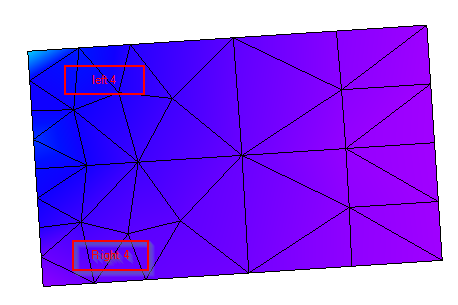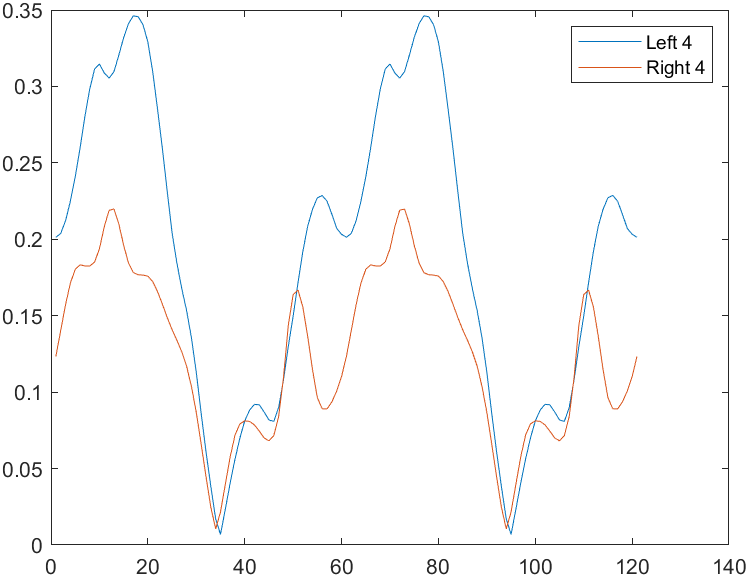

## speed List

1000~15000

skin Depth와 관련 

speedList=[1000:1000:15000];
skinDepth=

